# Course Project (MSE 422): Cathode Degradation Analysis

Source: E. Fensterle *et al.*, “Spatially Resolved Electrochemical Characterization of a PEM Fuel Cell Stack During Durability Testing,” *International Journal of Hydrogen Energy*, vol. 250, Art. no. 156060, July 2026, doi: 10.1016/j.ijhydene.2026.156060.

## From the research article

### Lab setup

The study targets the durability of proton exchange membrane fuel cells (PEMFC) for heavy-duty applications, and the need to identify and understand the aging mechanisms.The investigation on the membrane electrode assembly (MEA) is particularly important, since the MEA drives fuel-cell performance degradation during aging. The work focuses on spatially resolved aging effect across the active area, which is done with the CDDM (segmented current-density measurement board) and special expansion boards that transmit the current from the measurement segments to the Zahner device.

Testing condition: Coolant flow was kept constant, chosen so the inlet-to-outlet temperature difference was 10 K at the highest load point (1.8$A/cm^2$)

The test subject is the generic HyFaB stack with an active area of 280 $cm^2$ per cell and a project-specific MEA. Two builds were used: 

- a 10-cell stack for the durability test 

- an 8-cell stack for the BoL EIS sensitivity analysis.

### Testing procedure

A heavy duty load cycle was applied for more than 2000 hours to the stack. At regular intervals the stack was characterized with polarization curves, sensitivity tests, and electrochemical impedance spectroscopy (EIS) at cell level and spatially resolved. The full characterization sequence (after break-in, which aims to reach full cell performance) consisted of six polarization curves at different operating conditions, the partial sensitivity test, EIS at cell level and spatially resolved, and cyclic voltammetry.

Polarization curves were measured at 16 load points from 0 to 1.8 $A/cm^2$, in both descending and ascending order. The minimum current for stoichiometric operation was 0.3 $A/cm^2$ for the durability test and 0.5 $A/cm^2$ for the full sensitivity test. Sensitivity tests study the influence of operating conditions on performance, including temperature, humidity, pressure, and stoichiometry, at four different current densities.

EIS is a powerful method for separating the resistances of transport, conduction, and reaction processes, which occur at different frequencies. Both cell and spatially resolved impedance were measured galvanostatically. For the cell impedance the AC was 5% of the DC; for the spatially resolved measurements a slightly higher AC gave less noise.

### Result from the research

Cell voltage decrease over time, and the largest jump is between BoL (beginning of life) curve and the curve after 300 hours (25 cycles), about half the total loss happens in the first 300 hours (63.3 $\mu V/h$). The degradation rate at 1.8 $A/cm^2
$ is 15.7 $\mu V/h$ overall; excluding the reversible loss (comparing the after-air/air-start curves) it drops to 13.0 $\mu V/h$, and about 2.7 $\mu V/h$ of the loss is reversible.

Degradation impact increases with decreasing pressure, especially in the resistance of the oxygen reduction reaction (ORR). Temperature, humidity and stoichiometry variations did not show a strong influence of aging; the aging effect on sensitivity becomes evident under varying pressure. Increasing operating pressure enhances reactant availability and cell operation (as at BoL), but with a much more beneficial effect after aging: higher partial pressure improves oxygen transport to the catalyst layer, mitigating the impact of aging and supporting more uniform, robust performance. Aging effects are strongest at low pressures and elevated temperatures. Heterogeneity of the current-density distribution decreases with increasing humidity, pressure and stoichiometry, but increases with temperature. Mass-transport resistance is most strongly affected by stoichiometry, with pronounced increases in the outlet region at low stoichiometric ratios.

The active area is divided into 27 columns in the flow direction and averaged per column. Over time there is a visible shift of the current-density maximum toward the cathode inlet; the inhomogeneity increases and the maximum reaches higher values after 2300 hours. At the lowest load, local current densities at the air inlet become even lower, compensated by higher values in the middle; at higher loads there is no air-inlet effect, but an increased slope between the maximum (near the air inlet) and the middle-outlet area. Degradation therefore has a greater influence on the current-density distribution at lower temperatures (and at low stoichiometry).

The impedance spectra were interpreted through three points read off the Nyquist plot. The high-frequency resistance (HFR) is the ohmic loss: mainly the membrane (proton-transport) resistance, with smaller contributions from electronic contact resistances and electrode-related effects such as ionomer distribution and possible swelling. The low-frequency resistance (LFR) is the sum of all losses. The two arcs between the HFR, intermediate-frequency (IFR) and LFR intercepts correspond to two processes: ORR charge transfer on the cathode in the intermediate-frequency range, and mass transport in the low-frequency range. These were fitted with an equivalent circuit in which R₀ is the membrane resistance and the charge-transfer and mass-transport steps are each an R-CPE element.

Across the 2300 h test, the membrane held up well. Its resistance rose only slightly, with a clearer jump after 1150 hours, consistent with chemical aging of the membrane (radical attack that lowers proton conductivity) and possibly a small rise in interfacial contact resistance (e.g. between the gas-diffusion layer and the bipolar plate). Because this increase was small, the ohmic term changed little overall, and aging produced only minor effects in the average cell-level impedance.

The dominant degradation was on the cathode. The ORR charge-transfer resistance increased over time, driven by catalyst aging (Pt particle growth, dissolution and agglomeration, and carbon-support corrosion) that reduces the electrochemically active surface area (ECSA), with the loss concentrated in the cathode outlet region. The mass-transport resistance, which would normally grow as gas-diffusion paths become blocked (liquid-water accumulation, loss of GDL hydrophobicity, pore-structure changes, carbon-support corrosion), instead stayed roughly constant; the authors attribute this to the test avoiding high potentials and possibly being too short to trigger those mechanisms. In short, catalyst degradation mainly affected the ECSA and therefore the charge-transfer resistance, while the ohmic/membrane resistance remained largely unaffected.

## Aim of This Project

This project re-analyses the Fensterle et al.durability dataset to quantify how the PEMFC cathode degrades over 200 hours and turns that into a usable model for control. Instead of treating "BoL" (beginning of life) and "aged" as labels, it is used as a continuous parameter in a physic-informed model.

The work has 3 parts:

- Rebuild clean analysis tables from the raw load-cycle log, polarization curves and EIS spectra

- Fit a semi-empirical voltage model whose loss terms carry explicit aging

- Use that model to sweep operating points

- Search for setpoints that maximize net power as the stack ages

- Implement an optimal controller (explicit MPC) if time permits

## Methodologies

Everything downstream reads from a single SQLite database (cathode_degradation.db) built by the cleaning notebooks. The procedure to produce the result as follow:

- 'load_data.py': loading raw data points from load cycles, polarization curves, and sensitivity data

- 'eis_parser.py': loading reduced version of EIS data to tables

- 'eis_tier1.py': produce LFR/IFR/HFR (low/intermediate/high frequency resistance) data

- 'clean_load_data.ipynb': load all load cycle data in CSV files

- 'clean_polarization_data.ipynb': distill raw data into a small steady state table

- 'eis_sensitivity.py'

- 'eis_analysis.ipynb'

- 'eis_sensitivity.ipynb'

- 'temperature_model.ipynb': investigating the relationship of temperature to other parameters

- 'export_matlab.py': create metadata for MATLAB simulation

## Analysis and Discussion

### Degradation over time (EIS to explain "When")

Cell-level resistances were compared cell-against-itself over the same 10 channels, which removes the cell-to-cell offset and makes small aging changes measurable ($|t|>\approx2.3$ is significant for $n=10$). The degradation is dominated by the cathode: ORR charge-transfer rises while the membrane changes little, consistent with catalyst ECSA loss rather than ohmic growth.

*Table 1: Comparison between mechanism loss from data analysis and the paper*

The membrane proxy over-reads slightly because HFR at 1kHz sits on the tail of the ORR arc; the seeded circuit fit on the 10-cell mean spectrum confirms the membrane resistance rises only a few percent by 1150 hours and then plateaus, while fitted ORR climb about 10% by 2300 hours. The mass-transport term staying flat matches the paper's reading that the durability test avoided the high potentials that would drive GDL/carbon-support damage.

### Spatial degradation (EIS to explain "Where")

The 16-spatial-EIS zones were resolved from the cathode inlet (row 1) to the outlet. Losses rise strongly along the flow. Total resistance is about 3.5 times higher at the outlet than the inlet at BoL (34.8 vs 121.9 $m\Omega\cdot cm^2$ and aging concentrates at the outlet.

*Table 2: Results of predicting losses based EIS data*

In the first 1150 hours, the ORR resistance falls at the inlet and rises at the outlet; the paper's signature of catalyst redistribution along the channel. Over the full test, the total-loss increase is overwhelmingly an outlet effect (+4.6% at the inlet vs +29.8% at the outlet). The current density map tells the same story from the other side: the inhomogeneity increases with age and the current maximum shifts toward the cathode inlet, i.e. the healthy inlet carries relatively more load as the outlet degrades.

### Operating condition sensitivity 

The sensitivity sweeps (pressure, temperature, stoichiometry, humidity, all at 1.8 $A/cm^2$, at BoL and 2300 hours) show where aging changes the response to operating conditions. A uniform stack-2-stack offset cancels because BoL and aged spectra come from 2 different stacks and each stack's own low/high ratio is compared.

- Pressure is where aging shows most. The within-stack low-pressure penalty on total loss grows with age (LFR 100/200 kPaG ratio 1.27 -> 1.36). Tier 1 puts the increase in ORR (1.27-> 1.47); the circuit fit puts it in mass transport. The robust statement is the total-loss penalty, especially ORR depends on how the 2 arcs are split.

- Aging amplifies the outlet's sensitivity. The outlet total-loss ratio grows from BoL to 2300 h for low stoichiometry (2.7 -> 3.7) and low pressure (1.33 -> 1.55); the inlet barely moves.

- Stoichiometry drives outlet mass transport. At 2300 h, raising cathode stoichiometry from 1.6 to 2.1 cuts reference-cell MT from 101 to 46 $m\Omega\cdot cm^2$ and outlet total loss from 317 to 86 $m\Omega\cdot cm^2$, while cell voltage moves only $\approx16mV$. The outlet features capture what the cell voltage hides.

- Temperature optimum is $\approx70^\circ C$, region-dependent after aging. ORR and MT are both lowest near $70^\circ C$; after aging the inlet and middle stay optimal at $70^\circ C$ while the outlet is still improving at $75^\circ C$.

Reference-cell total resistance tracks cell voltage across conditions ($r\approx-0.9$), so these impedance features carry most of the operating-point voltage response and split it into membrane, ORR and mass-transport parts for the model.

### Thermal model

The voltage model needs a cell temperature, because membrane conductivity and the kinetic terms are temperature sensitive. The response that actually behaves well is the rise above the coolant inlet, not the absolute temperature, since the inlet is controlled but wanders by about $\pm1.5K$. A log-linear-in-current hypothesis was rejected (3 time worse than a straight line). The selected semi-empirical model is 

$T_{mean}=T_{in}+a+bj\frac{6}{F_{cl}}+cj^2+d(T_{in}-70)+e\frac{t}{1000h}$ with

- 
$$a=-0.369
$$


- 
$$b=1.683$$


- 
$$c=0.277$$


- 
$$d=-0.015$$


- 
$$e=-0.106 (K)$$


Cross validated RMSE = 0.09K across 19 test groups. Current density sets the rise through the coolant temperature rise (proportional to $\frac{j}{F_{cl}}$ plus a small quadratic term. Coolant flow is a real effect (6-8 $L/min$ lowers the rise at 1.8 $A/cm^2$ by $\approx0.75K$). The aging term is a small -0.1 K per 1000 hours drift, most likely sensor drift. Using waste heat instead of current as the driver fits each polarization curve slightly better but predicts the sensitivity tests worse, because at fixed current the extra loss from low pressure leaves with the exhaust water, not the coolant. These coefficients are exported to `thermal_params.csv` and used directly inside `degradation_func`

### The degradation regression (voltage model)

The degradation model is a semi-empirical single-cell voltage model fit by nonlinear least squares (`degradation_func.m`), not a plain linear regression. Aging enters the physical loss terms through two time factors (t = age in hours): a fast break-in factor and a slow linear-wear factor.


$$g_f=1-exp(-t/\tau), [\tau=300h; g_s=t/1000]$$


Cell voltage is the Nerst potential minus 3 losses, with aging acting on the ORR exchange current, the membrane resistance and the mass-transport amplitude

$U=E_{Nerst}-\eta_{act}-\eta_{ohm}-\eta_{mt}$, where

- 
$$\eta_{act} = \frac{RT}{\alpha F}\Big[\ln\frac{j+j_x}{j_0} - \gamma\ln\frac{p_{O_2}}{P_0}\Big], \quad j_0 = exp(\,\ln j_0 + j_{0f} g_f + j_{0s} g_s}\, e^{-\frac{E_a}{R}(\frac{1}{T}-\frac{1}{343.15}))$$


- 
$$\eta_{ohm} = j\,\mathrm{HFR}(t,j)\,(RH/0.35)^{-\nu}, \quad \eta_{mt} = exp(\ln c)(1 + c_f g_f + c_s g_s)\,exp(-k_T(T-343.15))\Big(\frac{j}{p_{O_2}/P_0}\Big)^{m}$$


*Table 3: Parameters for model fitting*

At 1.8 $A/cm^2$ and the nominal setpoint the model predicts a BoL -> 2300 hours voltage loss of about 34 mV, split roughly ohmic at 8 mV, mass transport at 17 mV, and kinetics at 10 mV. The kinetic loss is front-loaded (most of it in the first few hundred hours, the $g_f$ term), while mass transport grows mostly slowly (about 23% per 1000 h). 

Two caveats: 

- The HFR age slope is imposed from the Tier-1 EIS, so the model *presents* the ohmic degradation rather than independently fitting it; 

- The condition slopes (γ, ν, k_T, m) are only trustworthy inside the tested range $p_c [50-200 kPaG]$, $\lambda [1.6-2.1]$, $T[55-75^\circ C]$, $RH[0.3-0.9]$, and $j[0-2.3 A/cm^2]$).

clear; clc; close all
here = "C:\Users\dangs\Desktop\project\fuel_cell_project\Cathode Degradation of PEMFC";
if isempty(here), here = pwd; end
dataDir = fullfile(here, 'data');
outDir  = fullfile(here, 'results');
if ~exist(outDir, 'dir'), mkdir(outDir); end

### Visualization of the degradation function

`degradation_func` is swept on a $250\times250$ grid of current density ($0.3-2.3A/cm^2$) against age ($0-2300 h$) at the nominal setpoint, and nine quantities are plotted as heatmaps (x = current density, y = age). The grid separates the two axes of the model: current density drives the x-direction, aging the y-direction.

- Cell voltage falls left-to-right (load) and, more gently, bottom-to-top (age) from $\approx0.76V$ at low load to $\approx0.58V$ at 1.8 $A/cm^2$ and 2300 hours.

- Nernst potential is almost flat (1.18-1.19 V): thermodynamics barely moves over this window, so all the structure in cell voltage is loss.

- ORR loss grows with both load and age, by far the clearest aging signal, rising toward the top-right.

- Ohmic loss grows with load and age, roughly diagonal, reflecting both $j$ and the imposed HFR age slope.

- Mass-transport loss is small at low load and climbs steeply only at high current, with a mild age increase.

- Mean cell temperature depends almost entirely on load (coolant rise), so it is nearly horizontal; age has almost no effect.

- Exchange current density $(j_0)$ drops sharply in the first few hundred hours (the fast break-in factor) then flattens (the kinetic degradation signature).

- High-frequency resistance rises with age and current, a smooth gradient.

- Voltage loss vs BoL is zero along the bottom edge and grows upward, reaching roughly 34 mV at 1.8 $A/cm^2$ and 2300 hours. The headline degradation number, read directly off the surface.

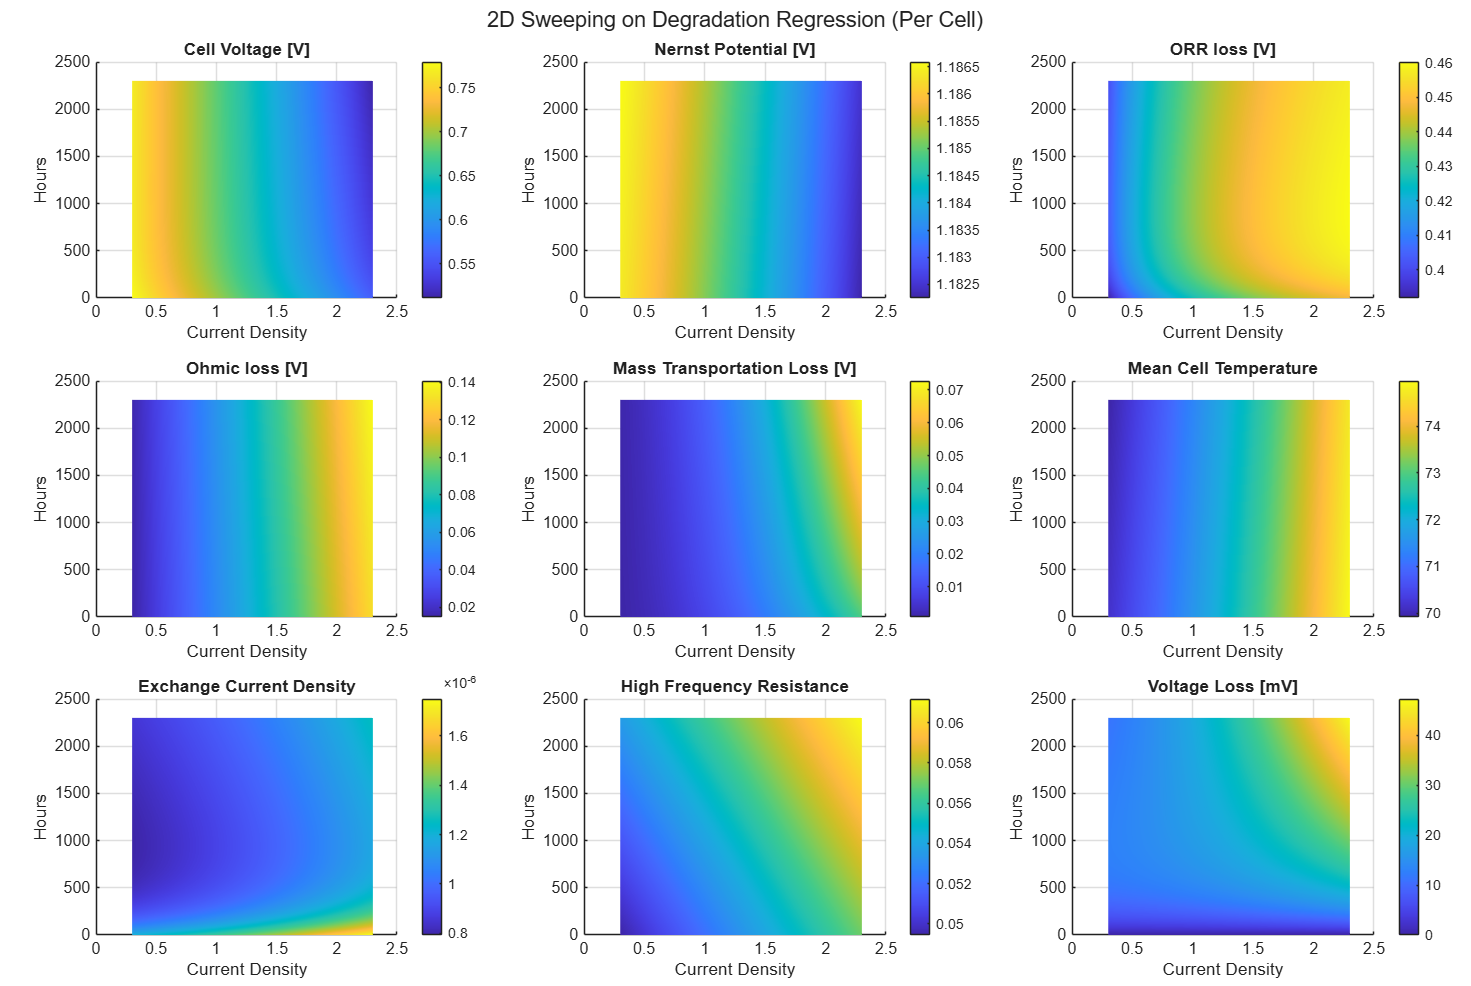

% Testing the degradation function on  default option
num_samples = 250;
current_density = linspace(0.3, 2.3, num_samples);
hours = linspace(0, 2300, num_samples);

% Create 2D grid of inputs
[J, H] = meshgrid(current_density, hours);

% Fields to plot (excluding 'params')
fields = {'U', 'E', 'eta_act', 'eta_ohm', 'eta_mt', 'T_cell', 'j0', 'HFR', 'dU_aging_mV'};
decoded_field = {'Cell Voltage [V]', 'Nernst Potential [V]', 'ORR loss [V]', 'Ohmic loss [V]', ...
                 'Mass Transportation Loss [V]', 'Mean Cell Temperature', 'Exchange Current Density', ...
                 'High Frequency Resistance', 'Voltage Loss [mV]'};
% Preallocate a struct of 2D matrices
results = struct();
for f = 1:numel(fields)
    results.(fields{f}) = zeros(num_samples, num_samples);
end

% Evaluate function across the 50x50 grid
for i = 1:num_samples
    for k = 1:num_samples
        out = degradation_func(J(i,k), H(i,k));
        for f = 1:numel(fields)
            results.(fields{f})(i,k) = out.(fields{f});
        end
    end
end

% Plot 3x3 grid
figure('Name', 'Degradation Properties (2D Sweep)');
fig = figure('Position', [100, 100, 1300, 900]); % [left, bottom, width, height]
tiledlayout(3, 3, 'Padding', 'compact');
sgtitle('2D Sweeping on Degradation Regression (Per Cell)')

for f = 1:numel(fields)
    nexttile;
    surf(J, H, results.(fields{f}), 'EdgeColor', 'none');
    view(2); % Top-down 2D heatmap view (remove this line for 3D surfaces)
    colorbar;
    title(decoded_field{f}, 'Interpreter', 'none');
    xlabel('Current Density');
    ylabel('Hours');
end

*Figure 1: 2D sweeping on Degradation Regression at Cell Level*

### Visualization of the fuel cell stack

`sweep_stack.m` takes the same grid to the stack and system level, reusing `degradation_func` for the per-cell voltage and adding the balance-of-plant (compressor + coolant pump) from `optimize_operating_point.m`. Three surfaces, stack voltage ($N\cdot U$), stack power, and net power (stack - compressor - pump), are each shown from three viewpoints: az/el (40, 28), (-140, 28) and (35, 52).

*Table 4: Nominal power at nominal operating conditions*

The $\approx0.6V$ that looked low is a single cell; the stack is simply $N=10$ of them in series (6 V at full load). Stack voltage falls with both load and age; stack power climbs with load and dips with age. Net power is stack power minus a compressor draw that grows with load (75 W at 0.3 $A/cm^2$ to 480 W at 1.8 $A/cm^2$) plus a near-constant of 9.5 W pump.

The gap between the stack-power and net-power surfaces is the parasitic cost, and it is the whole reason the optimization target is net power, not cell or stack voltage. Optimizing voltage alone has no interior optimum (raising pressure always helps) so the genuine trade-off (voltage gain vs compressor work) only appears once the balance-of-plant is charged for, which is a system-level quantity. This sweep is at the fixed nominal setpoint; letting pressure and the other knobs move per point is the optimized surface `optimize_operating_point.m` produces.

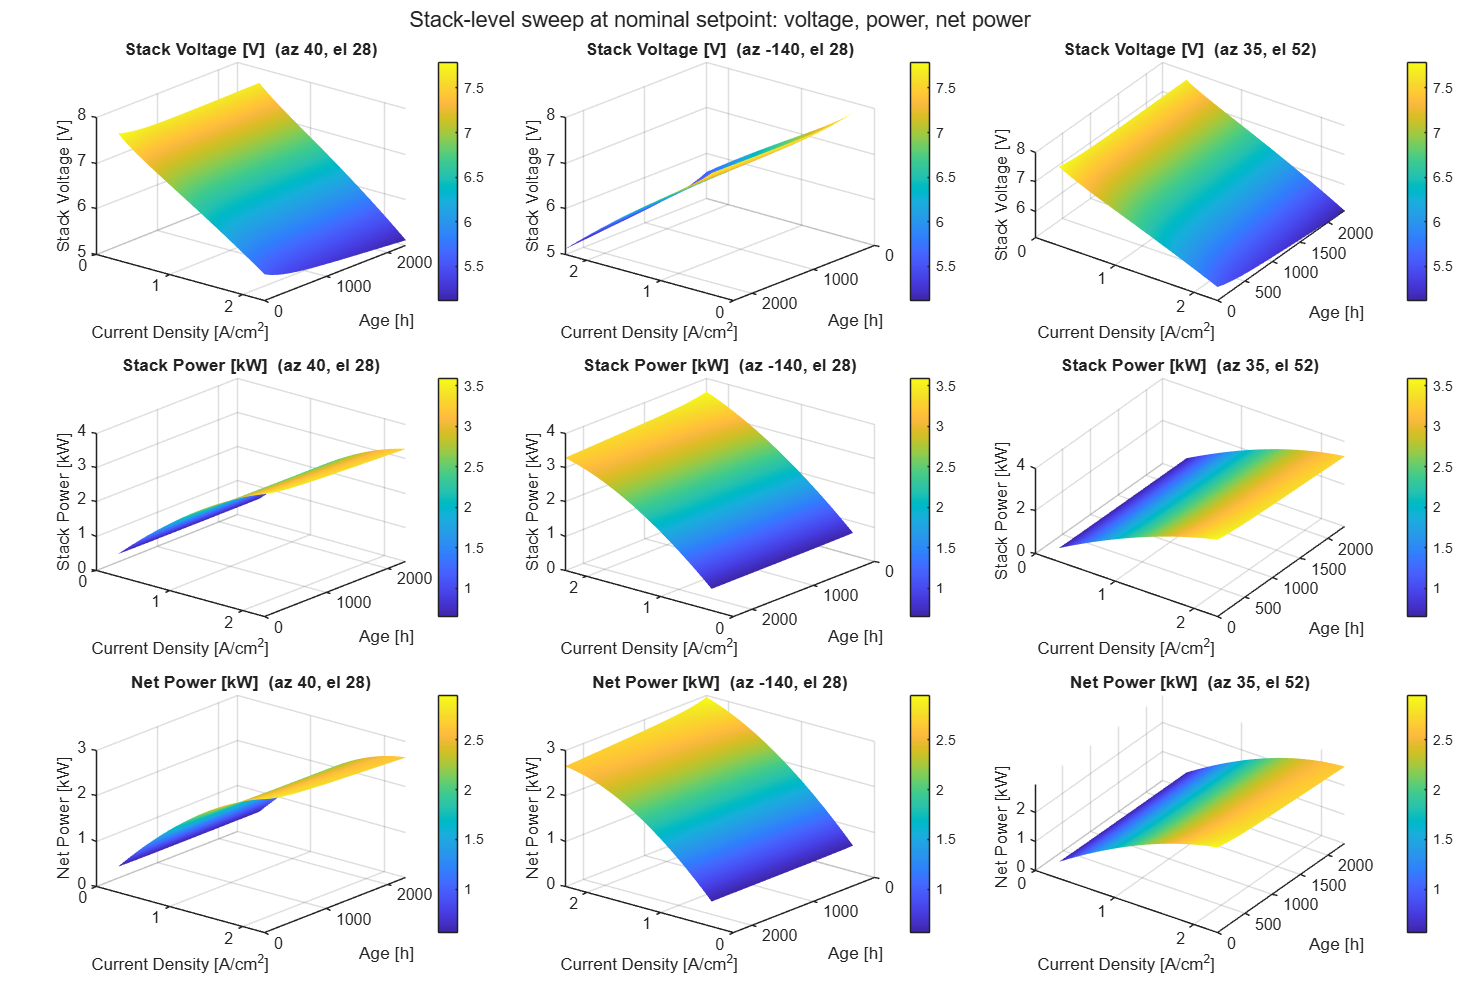

%% Constants (stack + balance of plant), from optimize_operating_point.m
P.R = 8.314; P.F = 96485; P.P0 = 101.325; % J/mol/K, C/mol, kPa
P.N = 10;    P.A = 280; % cells, active area per cell (cm^2)
P.T_amb = 298.15; % K, compressor inlet

P.eta_is = 0.70; P.eta_mot = 0.90; % compressor isentropic / motor eff.
P.dp_hum = 5; % kPa, humidifier + piping drop
P.dp_coef = [0.1495 0.00164]; % stack cathode drop dp = a*Q + b*Q^2

P.F_cl = 6.0; P.dp_cl = 47.5; P.eta_pump = 0.5; % coolant flow (L/min), drop (kPa), pump eff.
P.RH_a = 0.50; P.lam_a = 1.5; P.dpa = 10; % anode RH, stoich, anode-cathode p offset

x_nom = [150, 1.7, 70, 0.35]; % nominal [p_c kPaG, lambda_c, T_in degC, RH_c]

V_stack = zeros(num_samples); % V
P_stack = zeros(num_samples); % kW
P_net   = zeros(num_samples); % kW

for i = 1:num_samples
    for k = 1:num_samples
        s = fc_stack(J(i,k), H(i,k), x_nom, P);
        V_stack(i,k) = s.V_stack;
        P_stack(i,k) = s.P_stack / 1e3;
        P_net(i,k)   = s.P_net   / 1e3;
    end
end

views   = [40 28; -140 28; 35 52]; % [azimuth elevation]
metrics = {V_stack, 'Stack Voltage [V]'; ...
    P_stack, 'Stack Power [kW]'; ...
    P_net,   'Net Power [kW]'};

fig = figure('Name', 'Stack-level sweep', 'Position', [100 100 1300 1300*1.5]);
tiledlayout(3, 3, 'Padding', 'compact', 'TileSpacing', 'compact');
for m = 1:3
    for v = 1:3
        nexttile;
        surf(J, H, metrics{m,1}, 'EdgeColor', 'none');
        view(views(v,:)); grid on; colorbar
        xlabel('Current Density [A/cm^2]'); ylabel('Age [h]'); zlabel(metrics{m,2});
        title(sprintf('%s  (az %d, el %d)', metrics{m,2}, views(v,1), views(v,2)), ...
            'Interpreter', 'none');
    end
end
sgtitle('Stack-level sweep at nominal setpoint: voltage, power, net power')
print(fig, fullfile(outDir, 'fig_stack_sweep.png'), '-dpng', '-r130');

*Figure 2: Stack Level Sweeping at Nominal Setpoints: Voltage, Power, and Net Power*

## Limitations

The regression is a semi-empirical model fit to a single open dataset, and that limits how strongly it can be validated. The dataset covers one 2300-hour run under cyclic loading with essentially no repeated measurements, so there is no independent data to confirm that the fitted regression generalizes rather than simply interpolating this one history. The original study used the data to establish which degradation mechanisms are significant and where they act, but a little emphasis on "when" they develop over time, which is also the most important factor that this regression model relies on. The aging term are therefore support by the trend of a single Nerst equation and other empirical sub-models to represent the cell's behavior over long operation, so it's accuracy is tied to assumptions:

- A fixed activation energy

- An imposed HFR trend

- Only valid within the tested operating range (cannot generalize any further)

## Further improvement

The clearest improvement is validation data. Repeated runs, or measurements from a second stack aged under the same load cycle, would show whether the time dependent terms hold up or the regression is overfitted. More intermediate-age checkpoints matter most to reveal any dynamic behavior of the model. Beyond validation, the model only describes how the stack has aged as a function of elapsed time, so a dedicated degradation-rate model like how pressure, temperature, stoichiometry and humidity accelerate or slow the aging would let the regression predict rather than replay, and would support operating the stack for longer life. Reducing the reliance on the empirical sub-models, for example by fitting the ohmic term directly instead of imposing the HFR trend, and testing the fit against held-out operating points, would strengthen it further. The model is then ready to be applied for an optimal control system design on a separate report.

## Conclusion

This project re-analyzed the Fensterle et al. durability dataset and condensed it into a usable model. The cleaning pipeline rebuilt consistent tables from the raw load-cycle log, polarization curves and EIS spectra. The EIS analysis reproduces the study's findings on when and where the cathode degrades:

- Charge-transfer (ORR) dominated

- Concentrated at the cathode outlet, sharpest at low pressure

- The membrane and mass transport nearly unchanged

A semi-empirical voltage model folded these effects into explicit aging terms, predicting roughly 34 $mV$ of loss at 1.8 $A/cm^2$ by 2300 hours. By treating age as a continuous parameter rather than a beginning-of-life or aged label, the model becomes a physics-informed plant that can be swept, optimized and controlled, even if, as noted, its time-dependent behavior rests on a single unrepeated run. That plant is the foundation for the optimal control system design developed in a companion report.